# Converting the drawn image to XY-plot...

***Capture the screenshot -> Select/trim desired part of captured picture -> Finally plot the captured image to XY plane...***

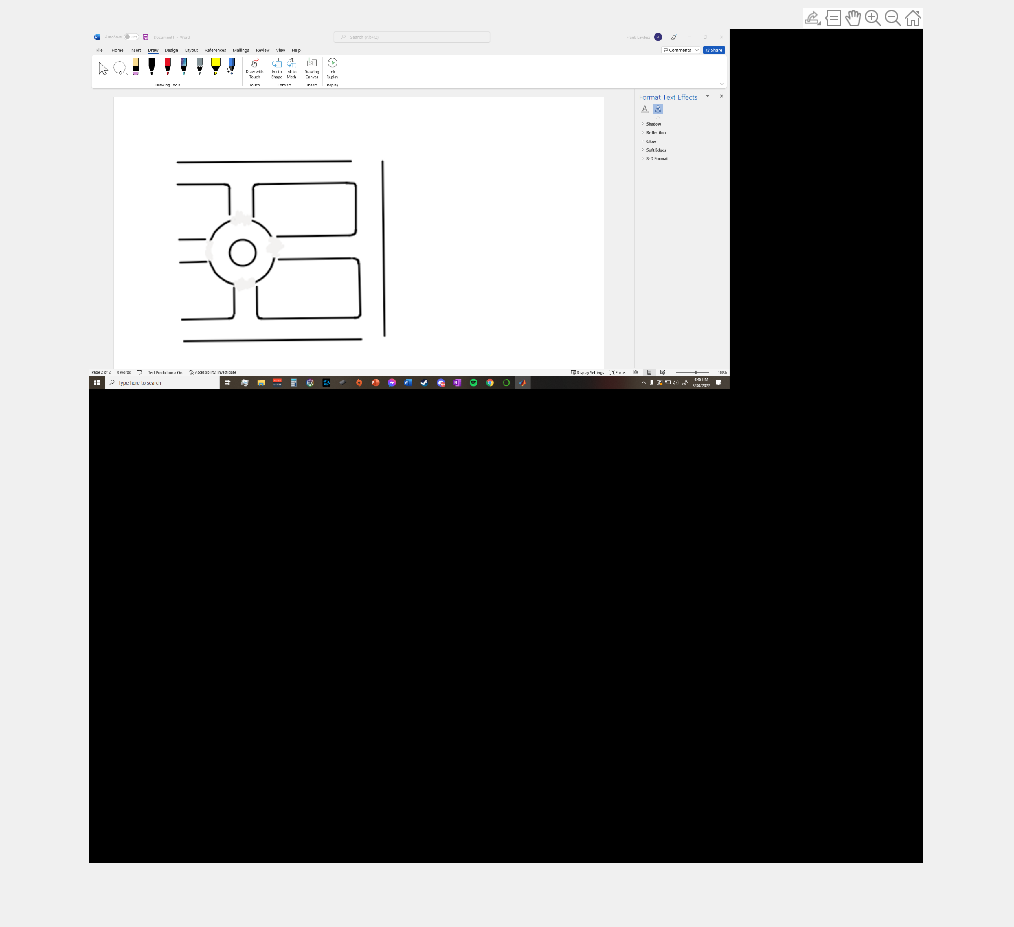

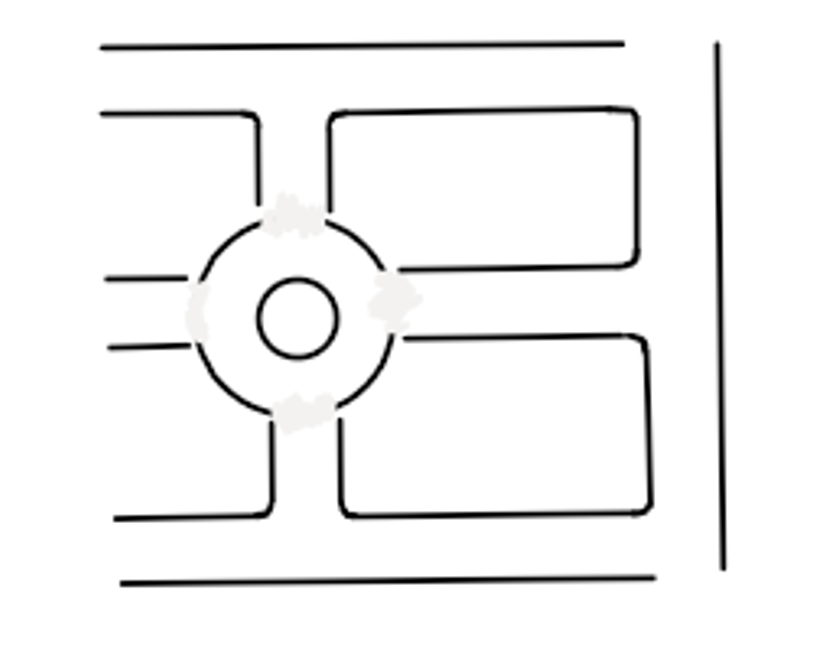

clc;
close all; 
clear all;

Image = screenShot(0,0,2500,2500);
imshow(Image);
selectPortion(Image);

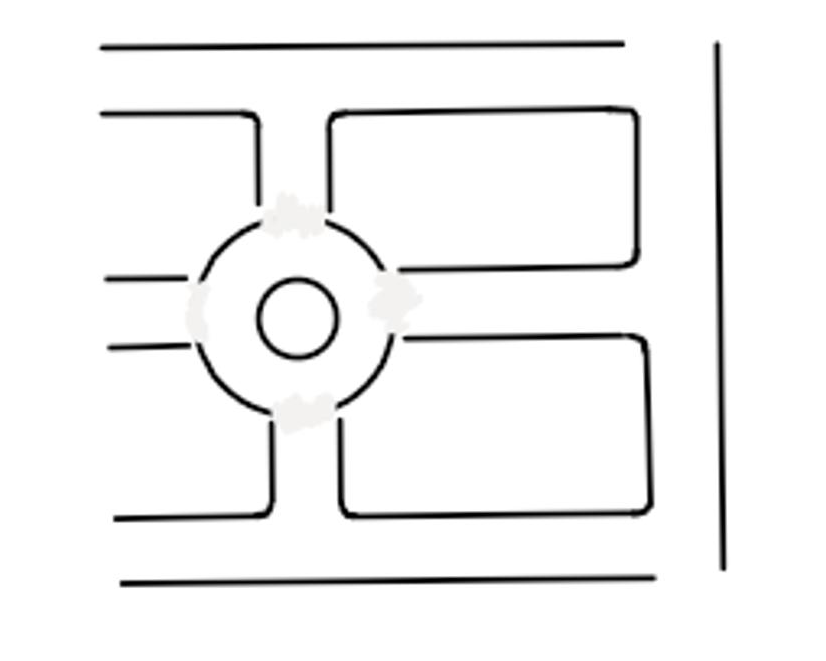

Image1 = imread('screenShot.jpg');         % Image 1-> Line...     
imshow(Image1);

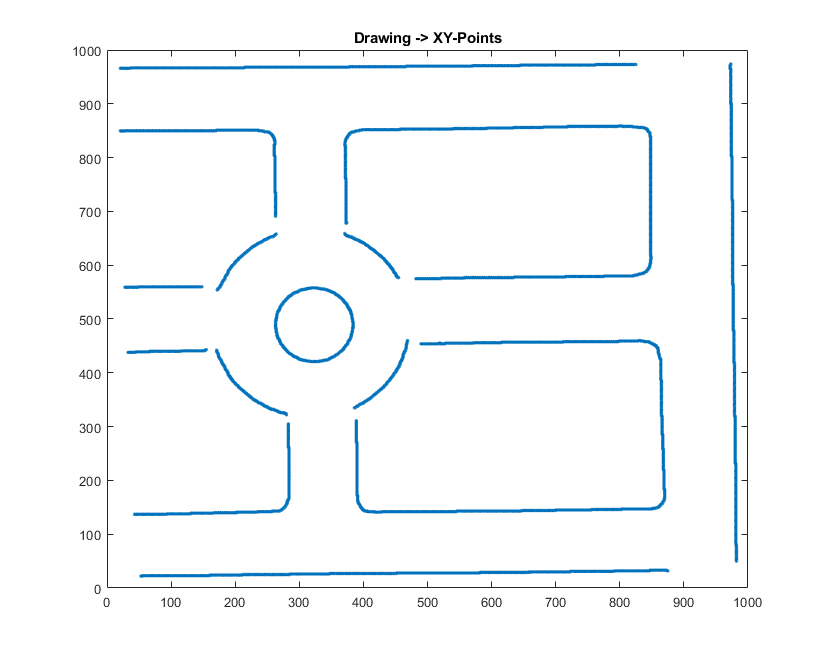

[y1,x1] = imageXYpoints(Image1,'Line');    % Getting points to plot...
map = [x1'; y1'];
plot(x1,y1,'.');                           % Plot the Points...
title('Drawing -> XY-Points');   


save("referencetrajectory_map_without",'map')

function [Y,X] = imageXYpoints(Image,Flag)     % Flag argument -> determine image type...
    if strcmp(Flag,'Line')                     
        [Y,X] = lineXYpoints(Image);           % Getting points -> Line type image...
    elseif strcmp(Flag,'Symbol')
        [Y,X] = symbolXYpoints(Image);         % Getting points -> Symbol type image...
    else                                       % Image enter flag value invalid...
        fprinf('Please enter the valid input image type!');
    end
end

% *******************************************************************************************************************************************************
%
% Logic/algorithm reference for the function 'symbolXYpoints' and 'lineXYpoints' below is taken form:  
%
% Author: Amir
% Date: 10/25/2021
% Title of program: Convert image pixels to xy-coordinates.
% Web address/URL: https://www.mathworks.com/matlabcentral/fileexchange/54799-convert-image-pixels-to-xy-coordinates.
%
%                                                           and 
% 
% Author/creator: Suresh Bojja
% Date: 10/25/2021
% Youtube channel: OPENBOX Education 
% Title: MATLAB CODES - Morphological Operations for Binary Images.
% Web address/URL: https://www.youtube.com/watch?v=YnvGyvx3uSg.
%
%********************************************************************************************************************************************************

% Function XY coordinates for line type images...
function [row,column] = lineXYpoints(Image)
  Image = imresize(Image,[1000 1000]);           % Resizing the image...
  Image = im2gray(Image);                        % Image -> Grayscale image...
  Bimage = imbinarize(Image,graythresh(Image));  % Grayscale image -> Binary image...
  Bimage = ~Bimage;                              % Flipping bits of Image...
  Bimage = bwmorph(Bimage,'thin',Inf);           % Thining the trace of image line...
  [row,column] = find(Bimage == 1);              % Finding the Pixel with white values...
  offsetYval = size(Bimage,1);                   % Setting number of rows value as offset...
  row = offsetYval - row;                        % Leveling the row value to get Y-value on plot...
end

% Function XY coordinates for Symbol type images...
function [row,column] = symbolXYpoints(Image)
    Image = imresize(Image,[1000 1000]);                 % Resizing the image...
    Image = im2gray(Image);                              % Image -> Grayscale image...
    Bimage = imbinarize(Image,graythresh(Image));        % Grayscale image -> Binary image...
    se = strel('disk',1);                                % Defining the structral element...
    dilatedImage = imdilate(Bimage,se);                  % Getting the dilated image...
    erodedImage = imerode(Bimage,se);                    % Getting the eroded image...
    Internal = dilatedImage & ~erodedImage;              % Getting the Internal boundary of image...
    external = dilatedImage & ~Bimage;                   % Getting the External boundary of image...
    boundaryImage = external;
    boundaryImage = bwmorph(boundaryImage,'thin',Inf);   % Thining the trace of image line...
    [row,column] = find(boundaryImage == 1);             % Finding the Pixel with white values...
    offsetYval = size(boundaryImage,1);                  % Setting number of rows value as offset...
    row = offsetYval - row;                              % Leveling the row value to get Y-value on plot...
end

%************************************************************************************************************************************
%
% Logic/algorithm reference for the function 'screenShot' and 'SelectPortion' below is taken form:
%
% Author/creator: unknown
% Date: 11/01/2021
% Youtube channel: CodingLikeMad
% Title: MATLAB CODES - Taking Screenshots with Matlab[Advanced Matlab].
% Web address/URL: https://www.youtube.com/watch?v=s19oD9bbU6U&t=140s
%
%                                                       and 
%
% Author/creator: unknown
% Date: 11/1/2021
% Youtube channel: let's dECodE
% Title: Screenshot taking using MATLAB.
% Web address/URL: https://www.youtube.com/watch?v=NxQfOLBAKA8&t=383s
%
%************************************************************************************************************************************


% Function for taking screenshot and converting it into image file...
function [RGBImage] = screenShot(Xt,Yt,Xb,Yb)
    captureObject = java.awt.Robot();             % creating the 'java.awt.Robot' object...
    pos = [Xt,Yt,Xb,Yb];                          % Setting dimension for amount of screen to be captured...

    diagonalPoints = java.awt.Rectangle(pos(1),pos(2),pos(3),pos(4));         % Creating the rectangle shpae with diagonal points...
    screenDisplay = captureObject.createScreenCapture(diagonalPoints);        % Take screen capture...
    % Converting the java image type to RGB image type and storing those values
    % into single row vector with uint8 element type...
    Image = typecast(screenDisplay.getRGB(0,0,screenDisplay.getWidth,screenDisplay.getHeight,[],0,screenDisplay.getWidth),'uint8');
    RGBImage = zeros(screenDisplay.getHeight,screenDisplay.getWidth,3,'uint8'); % Initializing the RGB image matrix will zero
    RGBImage(:,:,1) = reshape(Image(3:4:end),screenDisplay.getWidth,[])';       % Selecting the red pixel from row starting with third element and offset of 4...
    RGBImage(:,:,2) = reshape(Image(2:4:end),screenDisplay.getWidth,[])';       % Selecting the green pixel from row starting with second element and offset of 4...
    RGBImage(:,:,3) = reshape(Image(1:4:end),screenDisplay.getWidth,[])';       % Selecting the blue pixel from row starting with first element and offset of 4...
end

% Function for selecting certain portion for genetrated image and saving it in to certain format...
function selectPortion(Image)
    delete screenShot.jpg;                        % Deleteing the previously generated image by code...
    [y,x] = ginput(2);
    x = fix(x);
    y = fix(y);
    figure
    trimmedImage = Image(x(1):x(2),y(1):y(2),1:3);
    imshow(trimmedImage);
    imwrite(trimmedImage,'screenShot.jpg');
end

